## A Basic SISO Exmaple.

Given the uncertain plant, defined in real factored form with parametric uncertainty


$$\begin{array}{l}
P\left(s\right)=k\frac{s+a}{1+2\zeta \text{ }s/\omega {\text{ }}_{n\text{ }} +s^{2\text{ }} /{\omega \text{ }}_n^2 },\text{ }\\
k\in \left\lbrack 2,5\right\rbrack ,\text{ }\text{ }\text{ }a\in \left\lbrack 1,3\right\rbrack ,\text{  }\zeta \in \left\lbrack 0\ldotp 1,0\ldotp 6\right\rbrack ,\text{  }\omega {\text{ }}_{n\text{ }} \in \left\lbrack 4,8\right\rbrack \ldotp \text{ }
\end{array}$$
 

Close the loop with a feedback compensator $G\left(s\right)$, and a prefilter $F\left(s\right)\text{ }$such that the following specifications are satisfied:

- 
$$M\le 10%$$


- $t_{s\text{ }} \le 1\ldotp 5$ sec.

- $S\left(j\omega \text{ }\right)=|1/\left(1+L\left(j\omega \text{ }\right)\right)|\le 6$ dB

In the new object oriented QFT toolbox the plant is defined inan m-file or command line as

k=qpar('k',2,2,5,8);        
a=qpar('a',3,1,3,8);
z=qpar('z',0.6,0.3,0.6,8);
wn=qpar('wn',4,4,8,8);

num = [k*wn*wn k*wn*wn*a]; 
den = [1 2*z*wn wn*wn];
P = qplant(num,den);

Each of the uncertain parameters is definced as a `qpar` object. A qpar object such as `k` is defined usgin the syntex 

`par = qpar(name,nom,lbnd,ubnd,cases)`. 

where `name` is string; `nom`, `lbnd`, `ubnd` are scalaric numbers describing the nominl value, lower bound, and upper bound, respectively; cases is an optional input which tellsthe number of uncertain cases, i.e. the unmber of grid points. For exmaple

k = qpar('k',2,2,5,8)

k =   qpar with properties:

       name: 'k'
    nominal: 2
      lower: 2
      upper: 5
      cases: 8


Two or more `qpar` objects can be combined together into a `qexpression, `which stores the parametric description along with a list of all envolded `qpar` objects. For exmaple

exp = k*wn*wn

exp =   qexpression with properties:

    expression: '(k * wn) * wn'
          pars: [2×1 qpar]


The numerator an denomenator are defined using a raw vector of qpar, qexpression, or numeric objects. The first element is the n-order coefficient and so on. The result is a qpoly element with all coefficients and parameters

den = [1 2*z*wn wn*wn]

den = qpoly with coefficients

    s2: 1
    s1: '(2 * z) * wn'
    s0: 'wn * wn'


Finally, P is an instance of a `qplant` class, defined by two `qpoly` elemetns definning the numerator and denomenator.

P = qplant(num,den)

P =   qplant with properties:

          num: [1×1 qpoly]
          den: [1×1 qpoly]
         pars: [4×1 qpar]
    templates: []
      nominal: []
         info: 'generated from [num,den] data on: 13-Jan-2019 18:20:23'


Note that the preperties 'templates' and 'nominal' are empty. They require computation. The nominal case is computed by the command `cnom `as follows

w_nom = logspace(-2,2,200);
P.cnom(w_nom)

ans =   qplant with properties:

          num: [1×1 qpoly]
          den: [1×1 qpoly]
         pars: [4×1 qpar]
    templates: []
      nominal: [1×1 qfr]
         info: 'generated from [num,den] data on: 13-Jan-2019 18:20:23'


The nominal case that is computed is a `qfr` object. It acts very simailarly to Matlab's LTI object. Hance, a Bode plot is drawn by

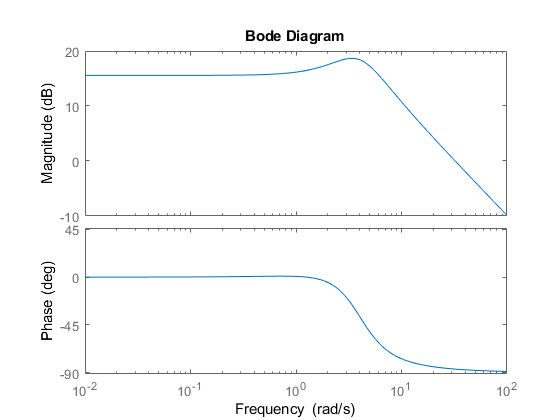

figure, P.nominal.bode()

If one wish to plot other cases (not the noiminal), the commands `bodcases` and `niccases` are useful. For exmaple, to plot the Bode for uniform grid of parameter cases

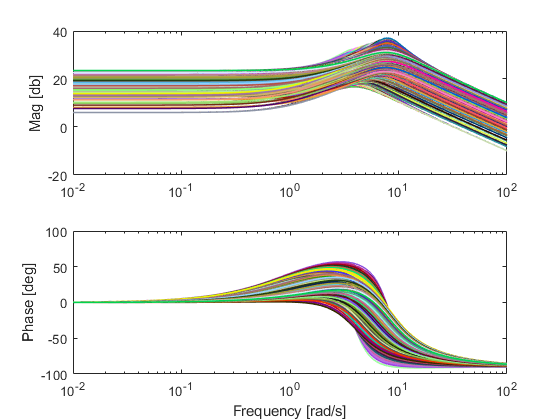

figure, P.bodcases()

A specific set of cases is shown by

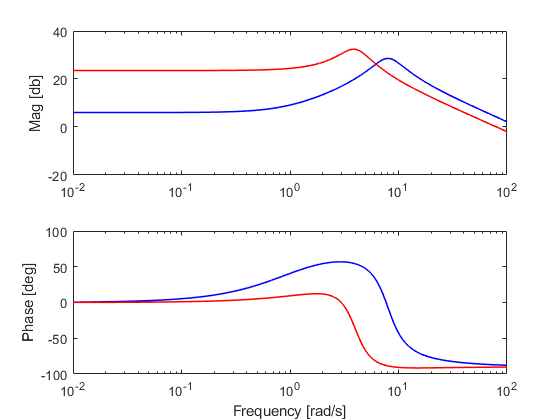

pars = [1 3; 2 5; 8 4; 0.3 0.3];
figure, P.bodcases(pars)

The templates are computed using `ctpl. To compute using recurcive edge grid (`'aedgrid'`) at selected frequencies and show`

w = [0.2 0.5 1 2 5 10 20 50];
P.ctpl('aedgrid',w)

Calculating templates by recurcive edge grid
--> for w=0.2 [rad/s] 
--> for w=0.5 [rad/s] 
--> for w=1 [rad/s] 
--> for w=2 [rad/s] 
--> for w=5 [rad/s] 
--> for w=10 [rad/s] 
--> for w=20 [rad/s] 
--> for w=50 [rad/s] 


ans =   qplant with properties:

          num: [1×1 qpoly]
          den: [1×1 qpoly]
         pars: [4×1 qpar]
    templates: [8×1 qtpl]
      nominal: [1×1 qfr]
         info: 'generated from [num,den] data on: 13-Jan-2019 18:20:23'


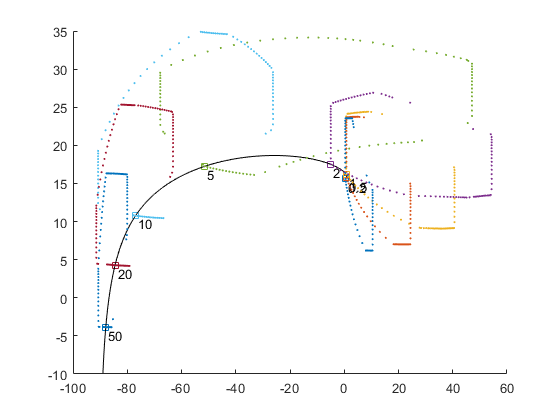

P.showtpl()

It is now time for the specifications. The 6dB sensitivity specs. are defined as a `qsps` object 

spec1 = qspc('odsrs',w,6)

spec1 =   qspc with properties:

         name: 'odsrs'
    frequency: [0.2000 0.5000 1 2 5 10 20 50]
        upper: [6 6 6 6 6 6 6 6]
        lower: []
      timespc: []
      timeres: []


The servo specifications are defined by

Creating array of size 4x6000


Reducing to 4x2916
Reducing to 4x2286
Reducing to 4x1547
Reducing to 4x1216
Reducing to 4x983
Reducing to 4x974
Reducing to 4x960
Number of good step-responses: 960
Plotting...
...done.


spec2 =   qspc with properties:

         name: 'rsrs'
    frequency: [50×1 double]
        upper: [50×1 double]
        lower: [50×1 double]
      timespc: [8×3 double]
      timeres: [109×3 double]


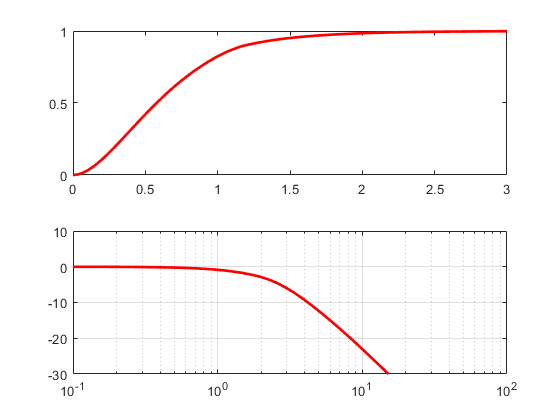

spec2 = qspc.rsrs([1.2 0.2],10,1.5,[],logspace(-1,2),2.85,3.1)

The two specs are 